# 多目标规划 序贯算法

本节课涉及的优化变量optimvar、优化问题optimproblem概念

MATLAB官方讲解：

[https://ww2.mathworks.cn/help/optim/ug/optimvar.html](https://ww2.mathworks.cn/help/optim/ug/optimvar.html)

[https://ww2.mathworks.cn/help/optim/ug/optim.problemdef.optimizationproblem.solve.html?searchHighlight=solve&s_tid=srchtitle_solve_2](https://ww2.mathworks.cn/help/optim/ug/optim.problemdef.optimizationproblem.solve.html?searchHighlight=solve&s_tid=srchtitle_solve_2)

当前模型：

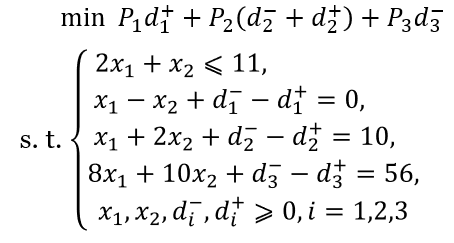

clc, clear
% 使用优化变量、优化问题来求解
% 创建优化变量x，dp和dm，类似于利用C++的类来创建对象
% 可以用来为目标函数和问题约束创建表达式
x = optimvar('x',2,'LowerBound',0);   % 定义两个变量x，最小值都为0
dp = optimvar('dp',3,'LowerBound',0); % 定义3个正偏差变量dp，最小值都为0
dm = optimvar('dm',3,'LowerBound',0); % 定义3个负偏差变量dm，最小值都为0

% 创建求最小值的优化问题p；optimproblem创建优化类问题
p=optimproblem('ObjectiveSense','min');


设置约束条件：$
2 x_{1}+x_{2} \le11  \\
x_{1}-x_{2}+d_{1}^{-}-d_{1}^{+}=0 \\
x_{1}+2 x_{2}+d_{2}^{-}-d_{2}^{+}=10 \\
8 x_{1}+10 x_{2}+d_{3}^{-}-d_{3}^{+}=56
$

% 设置优化问题的约束条件
p.Constraints.cons1 = ( 2*x(1)+x(2)<=11 );
% 注意，表示相等关系用的符号是"=="
p.Constraints.cons2=[x(1)-x(2)+dm(1)-dp(1)==0       
                     x(1)+2*x(2)+dm(2)-dp(2)==10
                     8*x(1)+10*x(2)+dm(3)-dp(3)==56];

设置目标函数：$\min P_{1} d_{1}^{+}+P_{2}\left(d_{2}^{-}+d_{2}^{+}\right)+P_{3} d_{3}^{-}$

% 设置目标函数
obj=[dp(1); dm(2)+dp(2); dm(3)];
% 单级目标函数的最优值goal，初始设为足够大的数
% 非常宽松的约束就等于没有约束，确保第一级的正常运算
goal=100000*ones(3,1);

for i=1:3
    % 重要：更新上一级的最优值，作为该级的约束条件;
    p.Constraints.cons3=[obj<=goal];
    p.Objective=obj(i);
    [sx,fval]=solve(p);     % 针对优化问题使用solve，会自动选择求解方式
    fprintf('第%d级目标求解为：\n',i)
    fval, xx=sx.x, sdm=sx.dm, sdp=sx.dp
    goal(i)=fval;
end

Solving problem using linprog.

Optimal solution found.



第1级目标求解为：


fval = 0

xx =          0
    5.6000


sdm =     5.6000
         0
         0


sdp =          0
    1.2000
         0


Solving problem using linprog.

Optimal solution found.



第2级目标求解为：


fval = 0

xx =     2.0000
    4.0000


sdm =     2.0000
         0
         0


sdp =      0
     0
     0


Solving problem using linprog.

Optimal solution found.



第3级目标求解为：


fval = 0

xx =     2.0000
    4.0000


sdm =     2.0000
         0
         0


sdp =      0
     0
     0


#### 代码中的solve()用来求解优化类问题，会自动判断问题类型并调用默认求解器

#### 求每一级目标（i=1，2，3）时相应变化的约束条件见PPT

三级都求完了，迭代结束，求得满意解为${\;x}_1 =2,x_2 =4$。即应该安排每天生产2台设备Ⅰ，4台设备Ⅱ。

注意多目标规划求得的叫做“满意解”而不是“最优解”，多目标规划的最终解没有最优的概念。因为在求解过程中，三个目标的重要性的设定是具有主观性的，假如改变三个目标的重要性排序，那么求解结果也会变。

本文件出自b站/公众号：数学建模BOOM

关注公众号：数学建模BOOM，回复"购买"，获取全套视频课程+配套PPT课件+代码文件+完善售后服务+后续课程更新

**版权所有，侵权必究。**本文件仅供购买者学习使用，不得随意传播，否则为侵权行为